net = importNetworkFromONNX('net.onnx');

mqttBrokerAddress = 'mqtt://192.168.21.251:1883';  % Replace with your broker address if needed
mqttUsername = 'password';                 % Replace with your MQTT username
mqttPassword = 'username';                 % Replace with your MQTT password
mqttTopic = 'hardware/log';                    % Define your topic

% Connect to the MQTT broker with authentication
mqttClient = mqttclient(mqttBrokerAddress, 'Username', mqttUsername, 'Password', mqttPassword);

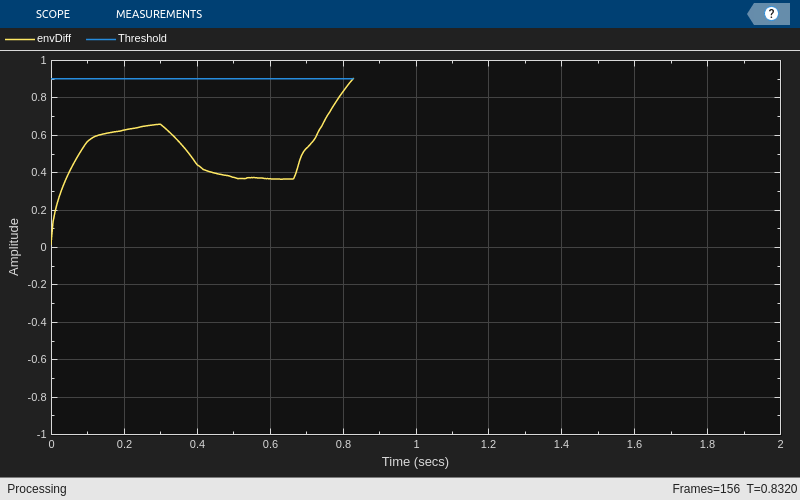

Error using icomm.mqtt.Client/write
Unable to write messages when the MQTT client is not connected. Use mqttclient to create a new connection.

frameLength = 256;
fftLength = 256;

% Using dsp.AudioFileReader
fileReader = dsp.AudioFileReader('Day2\Faulty1.wav', 'SamplesPerFrame', frameLength);
Fs = fileReader.SampleRate;

scope = timescope('SampleRate', Fs, 'TimeSpan', 2, 'BufferLength', Fs * 2, ...
                  'YLimits', [-1, 1], 'TimeSpanOverrunAction', 'scroll', ...
                  'ShowLegend', true);
scope.ChannelNames = {'envDiff', 'Threshold'};

bufferLength = round(5.0 * Fs);
audioBuffer = zeros(1, bufferLength);
bufferPosition = 1;
audioPositionSinceSync = 1;

maxPeak = 0.0;
startThreshold = db2mag(-30);

shortWinLength = round(0.3 * Fs);
longWinLength = round(2.0 * Fs);

shortRMS = dsp.MovingRMS(shortWinLength);
longRMS = dsp.MovingRMS(longWinLength);

deviceWriter = audioDeviceWriter('SampleRate', Fs);

% Wait for SYNC signal (sinusoid with amplitude larger than -30 dBFS)
while ~isDone(fileReader)
    signal = fileReader(); % read a new frame
    if max(signal) > startThreshold
        maxPeak = max(signal);
        break;
    end
end

while ~isDone(fileReader)
    signal = fileReader(); % read a new frame

    % Adaptive normalization
    signalPeak = max(abs(signal));
    if signalPeak > maxPeak
        maxPeak = signalPeak;
    end
    signal = signal / maxPeak; % scale the signal towards 1.0

    % Handle audio buffer
    frameLength = length(signal);
    emptyLength = bufferLength - bufferPosition + 1;
    % Make space for the new frame 
    if emptyLength < frameLength
        moveOffset = frameLength - emptyLength;
        audioBuffer(1:bufferPosition-moveOffset-1) = audioBuffer(moveOffset+1:bufferPosition-1);
        bufferPosition = bufferPosition - moveOffset;
    end
    % Fill in the buffer with the new frame
    audioBuffer(bufferPosition:bufferPosition+frameLength-1) = signal;
    bufferPosition = bufferPosition + frameLength;
    audioPositionSinceSync = audioPositionSinceSync + frameLength;

    % Process audio in the buffer (event detection)
    env1 = shortRMS(signal);
    env2 = longRMS(signal);
    envDiff = env1 + env2;
    threshold = 0.9;
    segments = envDiff > threshold;
    segmentIndices = find(segments);

    % Segment, classify, and report results
    if ~isempty(segmentIndices)
        % Extract the segment from the buffer for predi ction
        segment = audioBuffer(segmentIndices(1):segmentIndices(end));
        % Ensure the segment is long enough for spectrogram calculation
        if length(segment) >= frameLength
            % Define overlap less than the frame length
            overlap = round(0.75 * frameLength);

            % Convert to spectrogram or feature array
            spec = abs(spectrogram(segment, fftLength, overlap, fftLength, Fs));
            spec = imresize(spec, [128, 128]);  % Resize to match the model input size
            
            % Reshape the spectrogram to match the expected input size: [128, 128, 1]
            spec = reshape(spec, [128, 128, 1]);  % Grayscale input for the model

            % Predict using the ONNX model
            scores = predict(net, spec);
            
            % Get the class with the highest score
            [confidence, idx] = max(scores);
            
            % Manually map the index to the corresponding class label
            classLabels = ["F", "N"];  % Adjust the labels as necessary
            predictedLabel = classLabels(idx);  % Get the predicted class label
            
            predictionData = struct( ...
                'PredictedLabel', string(predictedLabel), ...
                'Position', audioPositionSinceSync, ...
                'Confidence', confidence ...
            );
            
            % Convert the struct to a JSON-formatted string
            predictionMessage = jsonencode(predictionData);
            % Publish the message to MQTT
            write(mqttClient, mqttTopic, predictionMessage);

            % Optionally, still print to MATLAB console for debugging
            fprintf("%s\n", predictionMessage);        
        end
    end

    %deviceWriter(signal);
    scope([envDiff, repmat(threshold, length(envDiff), 1)]);
end


%release(scope);
release(fileReader);
release(deviceWriter);